## Model Analysis

% load new models
clear
param.tissueSpecificSolver='thermoKernel';
switch param.tissueSpecificSolver
    case 'fastCore'
        baseFolderNew='~/drive/bioenergeticsPD/results/model/fastcore';
        load([baseFolderNew filesep 'synaptic_model/synaptic_model.mat'])
        load([baseFolderNew filesep 'synapticPD_model/synapticPD_model.mat'])
        load([baseFolderNew filesep 'synaptic_model/nonsynaptic_model.mat'])
        load([baseFolderNew filesep 'synapticPD_model/nonsynapticPD_model.mat'])        
    case 'thermoKernel'
        baseFolderNew='~/drive/bioenergeticsPD/results/model/thermokernel';
        load([baseFolderNew filesep 'test_SYN_new_model/SYN.mat'])
        load([baseFolderNew filesep 'test_SYNPD_new_model/SYNPD.mat'])
        load([baseFolderNew filesep 'test_ASYN_new_model/ASYN.mat'])
        load([baseFolderNew filesep 'test_ASYNPD_new_model/ASYNPD.mat']) 
end

% reshape
Allmodels.SYN.SYN=SYN;
Allmodels.SYNPD.SYNPD=SYNPD;
Allmodels.ASYN.ASYN=ASYN;
Allmodels.ASYNPD.ASYNPD=ASYNPD;

### 1. Perform validity checks (Sanity check)

performSanityChecks_xi

% save results of Sanity checks
AllTestSolution

AllTestSolution = 80×5 table
                                                    SYN2      SYNPD2      ASYN2     ASYNPD2     index 
                                                   _______    _______    _______    _______    _______

    ATP max, aerobic, glc                            10.62      10.62       10.6       10.6    {'YES'}
    ATP max, aerobic, citrate                        10.62      10.62       10.6       10.6    {'YES'}
    ATP max, aerobic, etoh                           10.62      10.62       10.6       10.6    {'YES'}
    ATP max, aerobic, glu-L                          10.62      10.62       10.6       10.6    {'YES'}
    ATP max, aerobic, gln-L                          10.62      10.62       10.6       10.6    {'

TableCheck

TableCheck = 9×5 cell array
    {'Exchanges, sinks, and demands have  lb = 0, except h2o'                                        }    {'model DOES NOT produce energy from water!'                                                                    }    {'model DOES NOT produce energy from water!'                                                                    }    {'model DOES NOT produce energy from water!'                                                                    }    {'model DOES NOT produce energy from water!'                                                                    }
    {'Exchanges, sinks, and demands have  lb = 0, except h2o and o2'                                 }    {'model DOES NOT produce energy from water and oxygen!'                                                         }    {'model DOES NOT produce energy from water and oxygen!'                                                         }    {'model DOES NOT produce energy from water and oxygen!'      

% save sanity check results
SanityCheck=cell2table(TableCheck);
SanityCheck.Properties.VariableNames={'CheckedItems','SYN','SYNPD','ASYN','ASYNPD'};
% writetable(SanityCheck,'~/drive/bioenergeticsPD/results/analysis/SanityCheck/SanityCheckResults.xlsx');
% writetable(AllTestSolution,'~/drive/bioenergeticsPD/results/analysis/SanityCheck/MetabolicFunctionResults.xlsx','WriteRowNames', true);

% check the uptake and excrete fluxes of each model
if 0
obj='ATPM';
% method='FBA';
method='eFBA';
plotExFluxes(Allmodels,obj,method)
end

### 2.Compare the exchange reactions in the PD model with PD CSF metabolites

% important exchange rxns to differiate control and PD (SYN)
Rxns={'EX_dopa[e]','EX_glc_D[e]','EX_trp_L[e]','EX_met_L[e]','EX_asn_L[e]','EX_orn[e]',...
    'EX_gln_L[e]','EX_lys_L[e]','EX_his_L[e]','EX_ile_L[e]','EX_Lpipecol[e]','EX_cit[e]',...
    'EX_4mop[e]','EX_ptrc[e]','EX_glyc_R[e]','EX_urea[e]','EX_lac_L[e]','EX_o2[e]','EX_co2[e]',...
    'LDH_Lm','LDH_L','NADH2_u10mi','CYOR_u10mi','CYOOm2i','CYOOm3i','ATPS4mi','DOPAVESSEC','EX_gluside_hs[e]'};
Rxns=Rxns';
% eFBA
compareWithCSFmets

Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.1.31 (Build date: 2024-5-6 11:08:30)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3653            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4578            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2999
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries  

Rxns

Rxns = 28×5 table
           Rxns           SYNflux    SYNPDflux    ASYNflux    ASYNPDflux
    __________________    _______    _________    ________    __________

    {'EX_dopa[e]'    }     1.0826       0.384           0            0  
    {'EX_glc_D[e]'   }    -0.7525     -0.3148     -0.4825      -0.2792  
    {'EX_trp_L[e]'   }    -0.8357     -0.8357     -0.8357      -0.8357  
    {'EX_met_L[e]'   }    -1.8909     -1.2779     -1.1715      -1.2528  
    {'EX_asn_L[e]'   }     0.4867      0.4867      0.4867       0.4867  
    {'EX_orn[e]'     }     25.366      25.366      25.366       25.366  
    {'EX_gln_L[e]'   }    -16.659     -16.624     -17.083      -16.869  
    {'EX_lys_L[e]'   }    -15.039     -14.939     -19.261      -18.947  
    {'EX_his_L[e]'   }    -6.3213     -7.2752     -6.9666      -5.9576  
    {'EX

% writetable(Rxns,'~/drive/bioenergeticsPD/results/analysis/CSFmets/CompareWithCSFmets.xlsx');

### 3. Identifying the ATP contribution and consumption reactions

% identify the metabolic pathways of energy generation in the models
ATPcontribution

### 4. Explore the ATP contribution under different ATPM value (energy requirement)

4.1 range from 10 to 660 umol/gDW/h (from minimum to maximum)

% calculate energy contribution under different ATPM value
range ='10-660'; % default energy range
energyPatternWithdifferntATPM

Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.1.31 (Build date: 2024-5-6 11:08:30)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3653            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4578            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2999
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries  

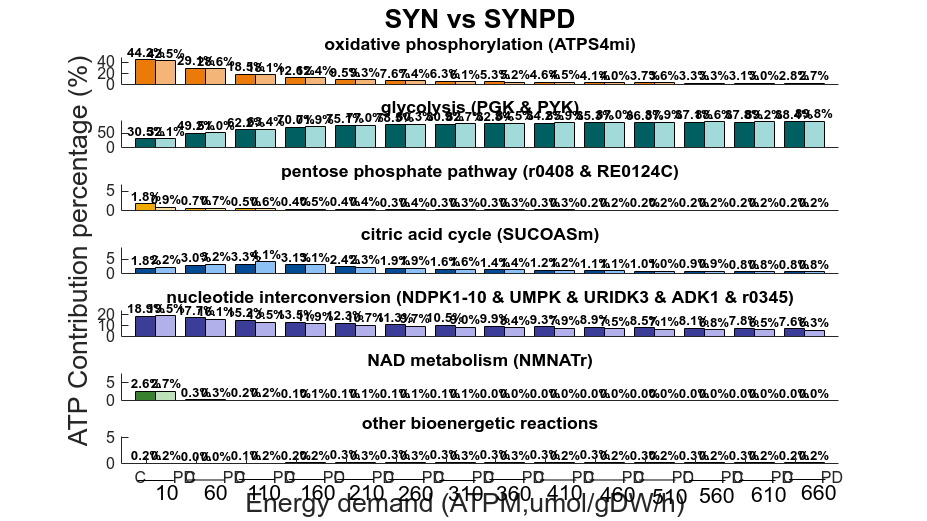

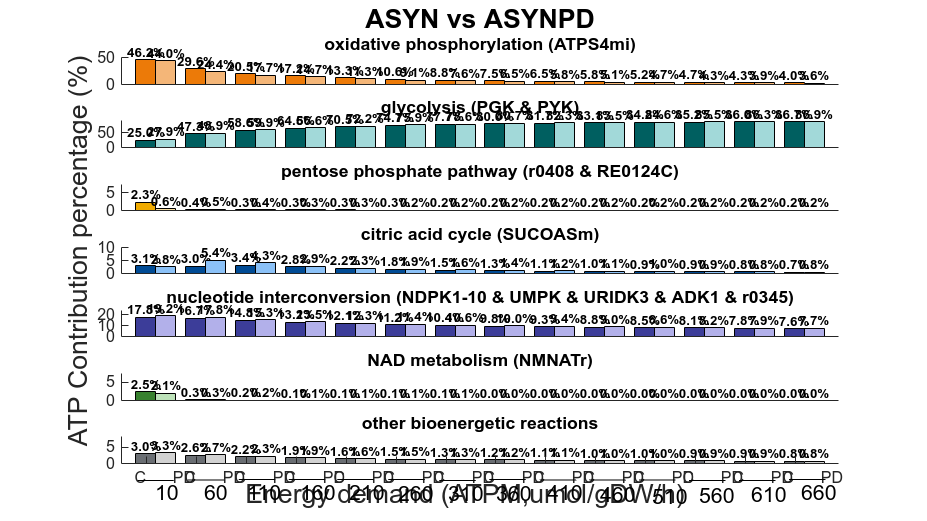

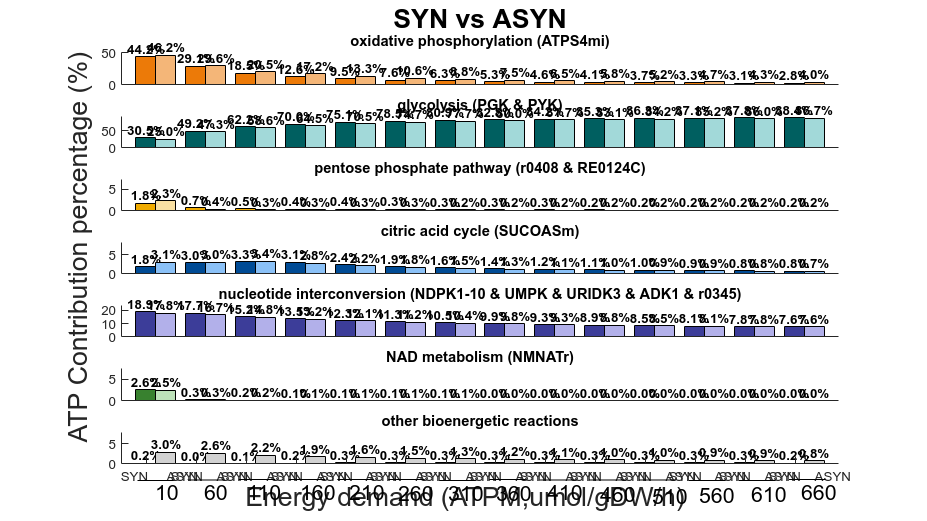

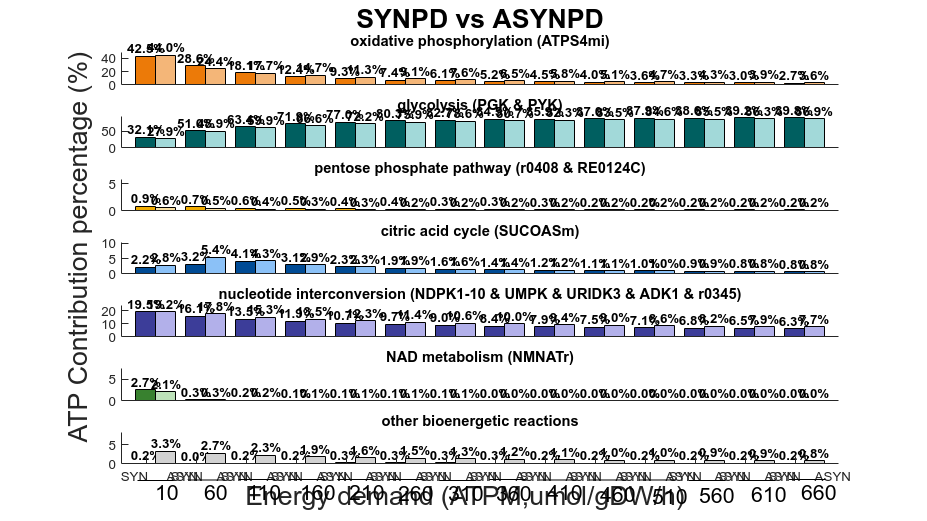

% plot ATP contribution on different ATPM value(10-660)
f='barchart';
plots_CandPD(demandATP,f,d) 

4.2 range from 10 to 100

% calculate energy contribution under different ATPM value
clear demandATP
range = '10-100';
energyPatternWithdifferntATPM

Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.1.31 (Build date: 2024-5-6 11:08:30)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3653            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4578            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2999
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries  

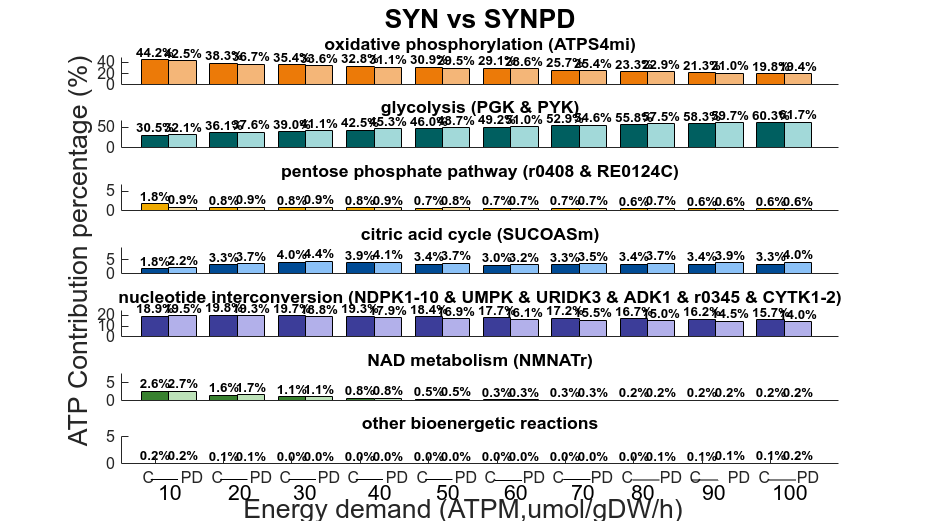

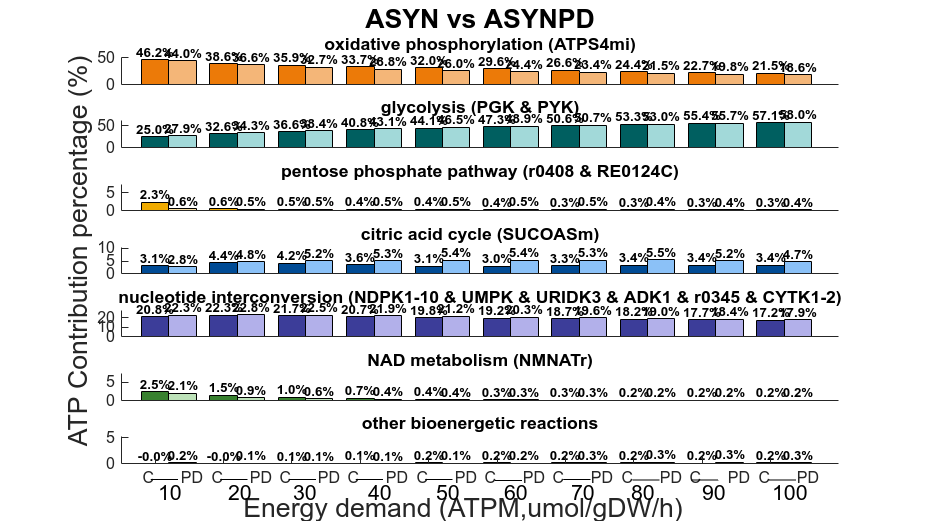

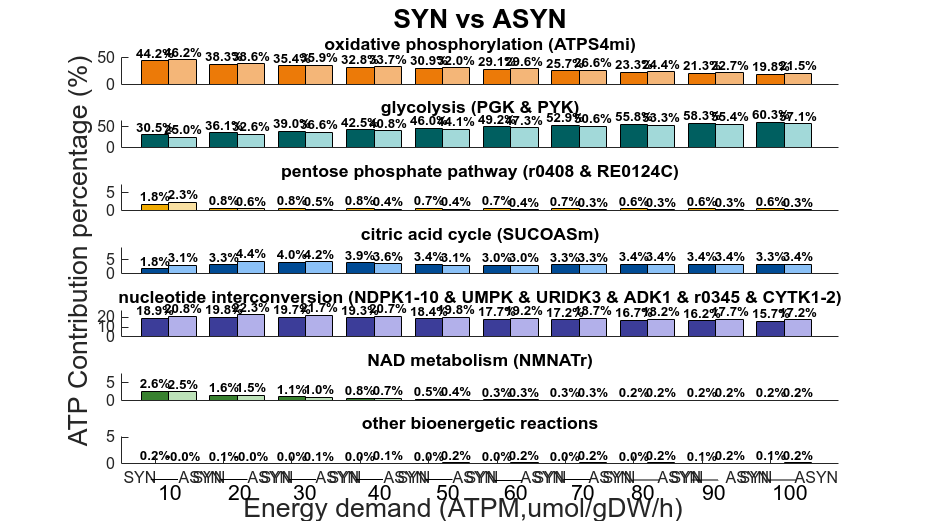

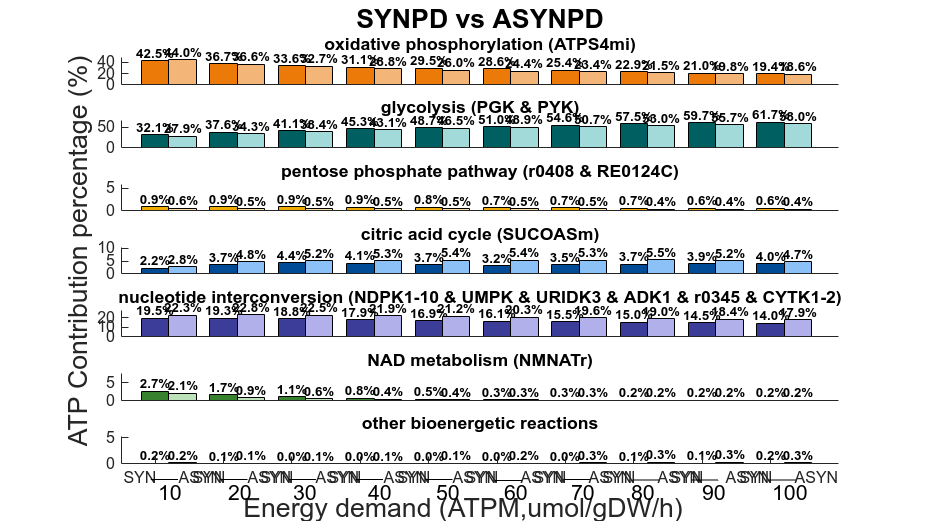

% plot other figures
f='barchart';
plots_CandPD_v2(demandATP,f,d) % ATPM from 10-100

4.3 plot flux changing trends, especially with ATPM ranging from 0 to 100

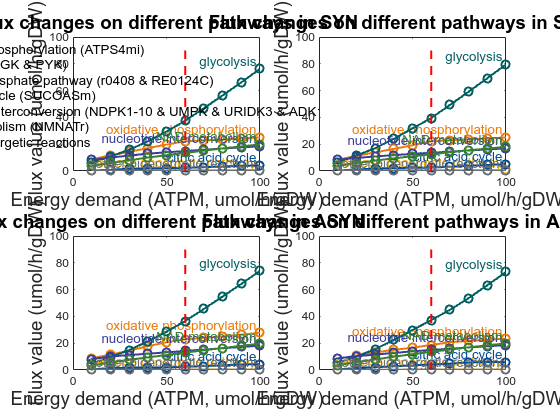

% flux changing trends plots, especially from 0 to 100
f='line';
plotChangingTrends(demandATP,f,d)

% compare old and new models
% plotRobustnessResults_OldandNew(demandATP)

### 5. complex I inhibition

Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.1.31 (Build date: 2024-5-6 11:08:30)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3653            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4578            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2999
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries  

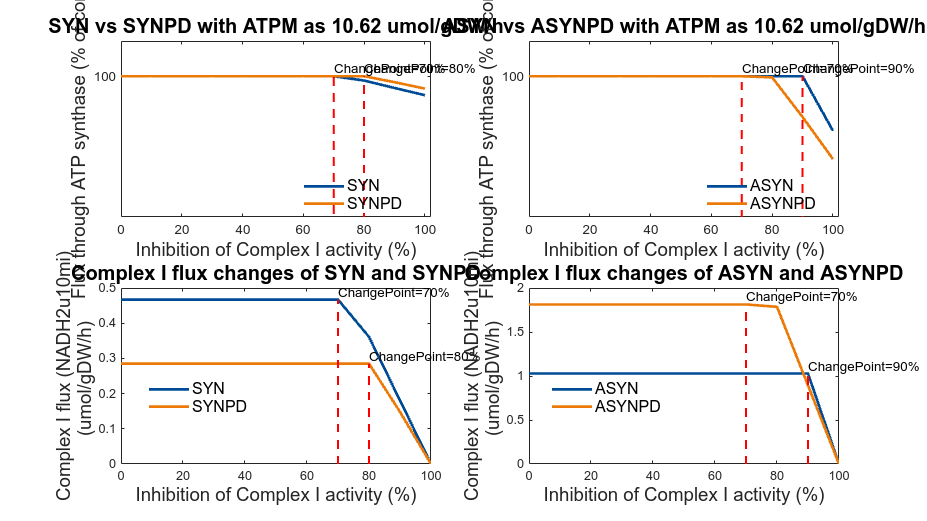

% with minimum ATPM value
method='eFBA';
ATPMvalue_SYN=10.62;%default lb
ATPMvalue_ASYN=10.62;%default lb
% generate complex I inhibition plots
ComplexInhibition

Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.1.31 (Build date: 2024-5-6 11:08:30)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3653            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4578            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2999
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries  

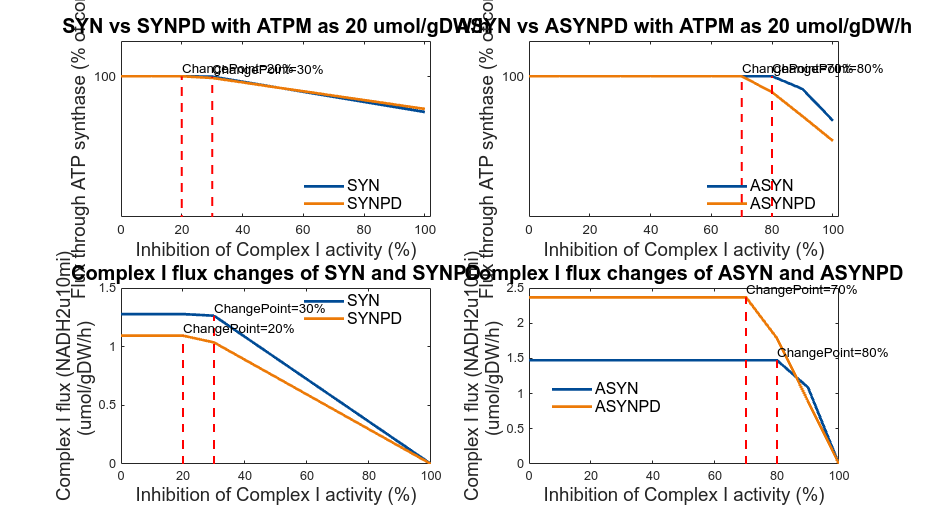

% with higher ATPM value
method='eFBA';
ATPMvalue_SYN=20;
ATPMvalue_ASYN=20;
% generate complex I inhibition plots
ComplexInhibition

Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.1.31 (Build date: 2024-5-6 11:08:30)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3653            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4578            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2999
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries  

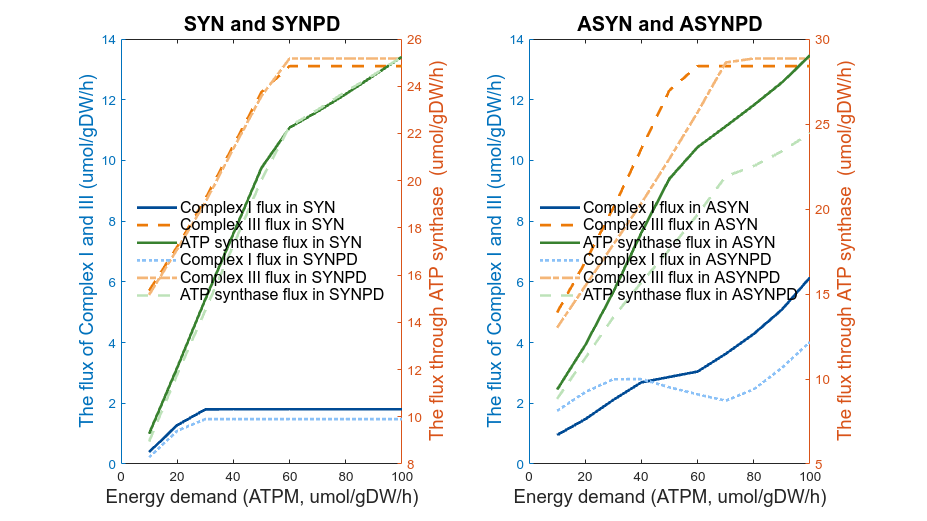

ATPMrange = 10:10:100;  % ATPM changing range
PlotComplexIFluxChanges

if 0
% change c value of linear part
ATPproductionRxn='ATPM';
obj='ATPS4mi';
ChangeCvalue_2
Cvalue
end

### 6. Sensitivity analysis of oxygen and glucose

#### 6.1 ATPS4mi vs O2 : Sensitivity analysis of oxygen

#### 6.2 ATPS4mi vs Glucose: Sensitivity analysis of glucose

Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.1.31 (Build date: 2024-5-6 11:08:30)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3653            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4578            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2999
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries  

Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.1.31 (Build date: 2024-5-6 11:08:30)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3615            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4568            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2946
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries  

Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.1.31 (Build date: 2024-5-6 11:08:30)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3471            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4396            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2846
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 9
Eliminator terminated.
Eliminator - tries   

Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.1.31 (Build date: 2024-5-6 11:08:30)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3783            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4781            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 3085
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 6
Eliminator terminated.
Eliminator - tries   

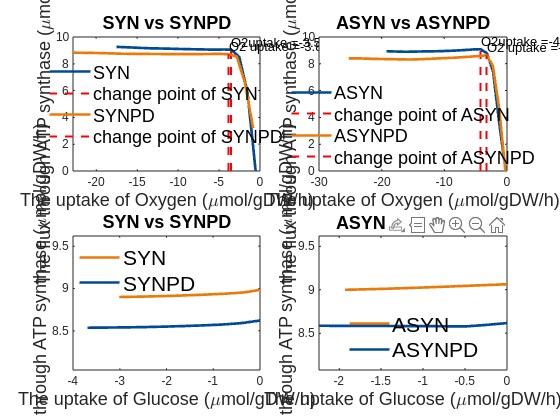

% objectiveFunction='ATPM'
ignoreUnconstrain=1;
method='eFBA';
ATPMvalue=10.62;% default/minimum ATPM
% ATPS4mi vs Oxygen or Glucose
plotSensitivity(Allmodels,ignoreUnconstrain,method,ATPMvalue)

Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.1.31 (Build date: 2024-5-6 11:08:30)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3653            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4578            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2999
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries  

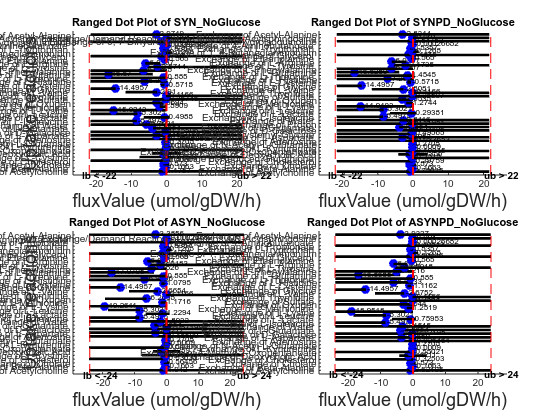

% check the uptake and excrete fluxes of each model
obj='ATPM';
% method='FBA';
method='eFBA';
% check the carbon sources when no glucose be uptaked
Allmodels1.SYN.SYN_NoGlucose=changeRxnBounds(Allmodels.SYN.SYN,'EX_glc_D[e]',0,'b');
Allmodels1.SYNPD.SYNPD_NoGlucose=changeRxnBounds(Allmodels.SYNPD.SYNPD,'EX_glc_D[e]',0,'b');
Allmodels1.ASYN.ASYN_NoGlucose=changeRxnBounds(Allmodels.ASYN.ASYN,'EX_glc_D[e]',0,'b');
Allmodels1.ASYNPD.ASYNPD_NoGlucose=changeRxnBounds(Allmodels.ASYNPD.ASYNPD,'EX_glc_D[e]',0,'b');
plotExFluxes(Allmodels1,obj,method)

## 7. PD energy rescue

% energy rescue
PDenergyRescue